# UNSUPERVISED LEARNING

1.  load the iris data set with the command `load 'fisheriris'`.  Two data structures will appear in your workspace: `meas` and `species`.  The data structure `meas` contains the flower measurements as a 150x4 matrix -- 150 samples, each with 4 variables.  The data structure `species` has text labels for each iris type; these labels are not needed for the clustering exercises here.  

load fisheriris
meas

meas =           5.1          3.5          1.4          0.2
          4.9            3          1.4          0.2
          4.7          3.2          1.3          0.2
          4.6          3.1          1.5          0.2
            5          3.6          1.4          0.2
          5.4          3.9          1.7          0.4
          4.6          3.4          1.4          0.3
            5          3.4          1.5          0.2
          4.4          2.9          1.4          0.2
          4.9          3.1          1.5          0.1


2.  Cluster the iris data set using `kmeans` and create a dendrogram using using matlab's `linkage.m`. Compare the results.

[idx, C] = kmeans(meas,3)

idx =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


C =        5.9016       2.7484       4.3935       1.4339
         6.85       3.0737       5.7421       2.0711
        5.006        3.428        1.462        0.246


% Correction
idx = kmeans(meas,3,"Distance","cityblock","Replicates",5)

idx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


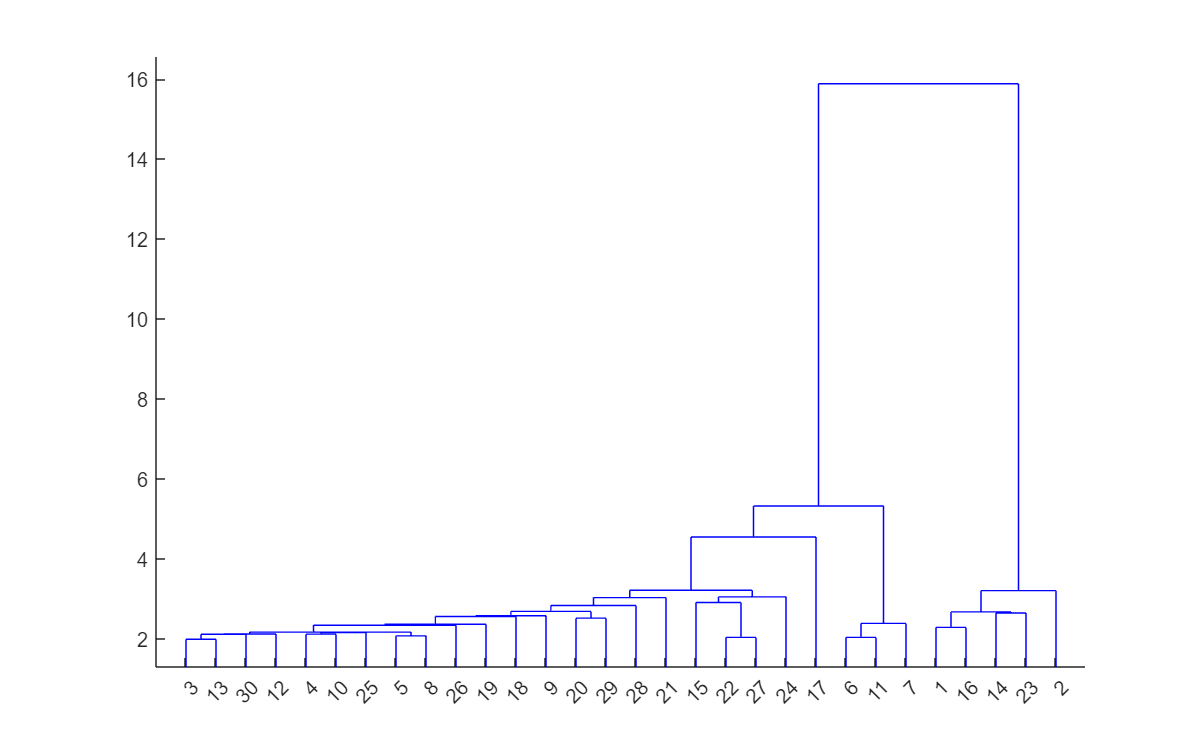


d = pdist(meas);
m = squareform(d);
ml = linkage(m);
dendrogram(ml)

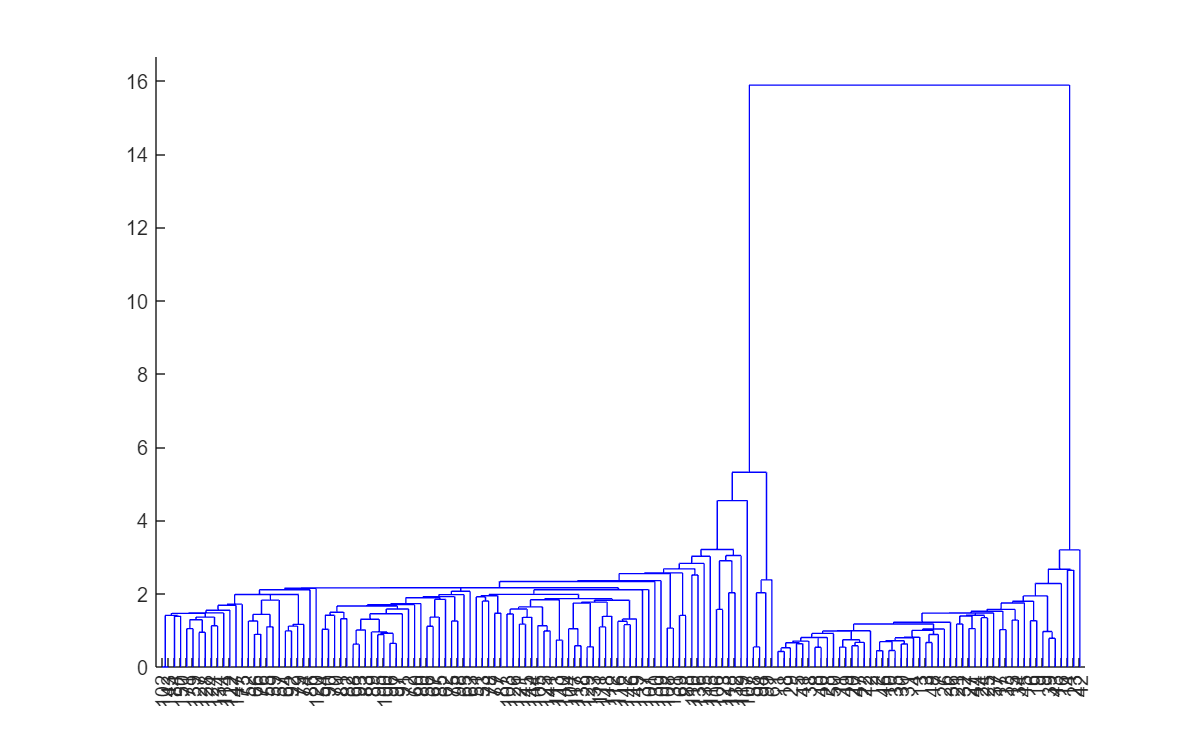

% Correction: putt 150 leaves
dendrogram(ml,150)

3.  Run `origbcm.m` on a dataset of 8 normalized random vectors.  Comment on the result.

rs = 0;
p8data = .7*ones(8)+.3*eye(8);
p8data = normc(p8data);
p8data'*p8data

ans =             1      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968
      0.97968            1      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968
      0.97968      0.97968            1      0.97968      0.97968      0.97968      0.97968      0.97968
      0.97968      0.97968      0.97968            1      0.97968      0.97968      0.97968      0.97968
      0.97968      0.97968      0.97968      0.97968            1      0.97968      0.97968      0.97968
      0.97968      0.97968      0.97968      0.97968      0.97968            1      0.97968      0.97968
      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968            1      0.97968
      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968      0.97968            1


b0 = initorigbcm(8,2,rs)

b0 = struct with fields:
    wts: [0.62945 0.81158 -0.74603 0.82675 0.26472 -0.80492 -0.443 0.093763]
     rb: 0

bf = origbcm(b0,p8data,100000,.005,rs)

bf = struct with fields:
    wts: [2.2045 3.2723 -2.2539 3.2704 0.57052 -2.3536 -1.5646 -0.062638]
     rb: 1.0817

bf.wts*p8data

ans =        1.3395       1.4917      0.70406       1.4915       1.1066      0.68986      0.80232       1.0164


% Correction:
ni=initorigbcm(8,2,rs)

ni = struct with fields:
    wts: [0.62945 0.81158 -0.74603 0.82675 0.26472 -0.80492 -0.443 0.093763]
     rb: 0

pats=normc(rand(8))

pats =       0.44513      0.19688      0.41311      0.18446      0.28045      0.46481      0.57317      0.52382
      0.44856      0.42746       0.4612     0.030755      0.24389      0.49451      0.20328      0.56403
     0.073272       0.3698      0.45231       0.0647      0.48932      0.18087      0.34953      0.32174
      0.45122      0.44789      0.23873      0.54851      0.50829      0.44538      0.13366     0.081506
      0.44497       0.3061      0.39895      0.46283      0.11945      0.42926      0.44867     0.087779
      0.22564      0.01667      0.10419      0.21122      0.31306      0.10655      0.15235      0.15141
      0.37204      0.39637      0.42973      0.63295      0.28482     0.077974      0.30216      0.49431
     0.065961      0.43598     0.019375     0.022945      0.41313      0.32656       0.4175      0.14951


pats'*pats

ans =             1      0.82476      0.89382      0.83875      0.75645      0.90854      0.80622      0.81351
      0.82476            1       0.8553      0.72514      0.90287      0.87571      0.83052      0.79022
      0.89382       0.8553            1       0.7297      0.78168      0.83041      0.85335      0.90762
      0.83875      0.72514       0.7297            1      0.68086      0.63497      0.64858      0.56841
      0.75645      0.90287      0.78168      0.68086            1       0.8076      0.80912      0.74377
      0.90854      0.87571      0.83041      0.63497       0.8076            1      0.85841      0.75807
      0.80622      0.83052      0.85335      0.64858      0.80912      0.85841            1      0.81248
      0.81351      0.79022      0.90762      0.56841      0.74377      0.75807      0.81248            1


nf=origbcm(ni,pats,2000000,.002,rs)

nf = struct with fields:
    wts: [552.2 -262.2 42.611 444.5 -319.44 -668.19 -75.133 -166.93]
     rb: 8

nf.wts*pats% responese for pattern

ans =    1.2588e-07   5.6911e-08   6.7083e-09  -5.2874e-08   2.2822e-08           64   4.8264e-08  -2.9126e-08


# LANGUAGE

Create an SRN model of the grammar below.  Generate a list of training strings. 

Test the model on grammatical strings, such as BPXXRJXXXRQE

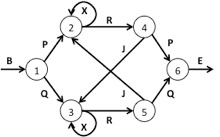

% setup list generation

reber.ind = [ % col->row weight
    0 1 0 0 0 0 0 0;
    0 0 2 3 0 0 0 0;
    0 0 4 0 5 0 0 0;
    0 0 0 4 0 5 0 0;
    0 0 0 6 0 0 2 0;
    0 0 6 0 0 0 3 0;
    0 0 0 0 0 0 0 7;
    0 0 0 0 0 0 0 0;];
reber.prob = [ % 0.5 for two output, 1 for one output
    0    1    0    0    0    0    0    0;
    0    0    0.5  0.5  0    0    0    0;
    0    0    0.5  0    0.5  0    0    0;
    0    0    0    0.5  0    0.5  0    0;
    0    0    0    0.5  0    0    0.5  0;
    0    0    0.5  0    0    0    0.5  0;
    0    0    0    0    0    0    0    1.0;
    0    0    0    0    0    0    0    0;];
reber.labels = 'BPQXRJE';

% init net
n0=initnet3srnx(8,12,8,2,2,rs)

n0 = struct with fields:
        wih: [12×8 double]
         hh: [12×12 double]
      hbias: [-0.82897 -0.47504 0.60203 -0.94156 0.85771 0.46066 -0.022782 0.15705 -0.52543 -0.082302 0.92618 0.093611]
      whout: [8×12 double]
      obias: [-0.16451 0.9661 -0.39709 0.4022 0.33268 0.078253 0.39621 0.33306]
    context: [0 0 0 0 0 0 0 0 0 0 0 0]


% make training list
list2k = makestringlist(reber,2000)

list2k = struct with fields:
      list: [1 2 5 6 4 5 3 7 8 1 2 4 5 6 5 3 7 8 1 2 4 4 5 6 4 5 6 4 5 6 5 3 7 8 1 3 4 5 3 7 8 1 3 4 4 4 4 4 4 4 5 6 5 2 7 8 1 2 4 5 2 7 8 1 3 5 3 7 8 1 3 5 6 4 4 4 4 4 5 6 5 3 7 8 1 3 4 5 6 5 2 7 8 1 2 5 2 7 8 1 3 4 5 6 5 6 4 4 4 5 6 5 6 4 4 5 6 4 4 … ]
    states: [1 2 3 5 4 4 6 7 1 2 3 3 5 4 6 7 1 2 3 3 3 5 4 4 6 3 3 5 4 6 7 1 2 4 4 6 7 1 2 4 4 4 4 4 4 4 4 6 3 5 7 1 2 3 3 5 7 1 2 4 6 7 1 2 4 6 3 3 3 3 3 3 5 4 6 7 1 2 4 4 6 3 5 7 1 2 3 5 7 1 2 4 4 6 3 5 4 4 4 4 6 3 5 4 4 4 6 3 3 3 5 4 6 3 5 4 6 3 3 … ]
       ind: [1 10 19 35 42 57 64 70 85 94 100 134 140 152 158 164 170 176 189 199 205 221 236 246 252 259 274 280 286 294 303 309 320 336 344 358 366 384 396 404 415 421 448 454 465 473 480 487 494 504 510 517 543 567 575 591 598 604 619 625 634 643 … ]

% train net
nf=bp3srn(n0,list2k,30000,0.02,0)

nf = struct with fields:
        wih: [12×8 double]
         hh: [12×12 double]
      hbias: [-0.82871 0.26555 -0.26226 -1.0866 1.0391 0.051395 0.37243 -0.87969 -0.96292 1.1571 2.2402 0.18981]
      whout: [8×12 double]
      obias: [-2.9316 -2.3532 -1.8573 -2.1686 -2.2413 -2.9909 -2.34 -2.1223]
    context: [0.89679 -0.02264 0.92317 0.77898 -0.60054 -0.78078 0.82537 -0.95399 0.70655 0.9552 0.9931 0.90185]

% BPXXRJXXXRQE = 124456444537
[s h s2]=stringprocv4X(nf,[1 2 4 4 5 6 4 4 4 5 3 7],reber)

lets = 'BPXXRJXXXRQE'

s =     'B P 0.000 0.493 0.523 0.000 0.000 0.001 0.000 0.000
     P X 0.000 0.000 0.001 0.508 0.484 0.000 0.000 0.000
     X X 0.000 0.000 0.000 0.440 0.590 0.000 0.001 0.000
     X R 0.000 0.001 0.000 0.456 0.587 0.000 0.000 0.000
     R J 0.000 0.402 0.204 0.000 0.000 0.477 0.001 0.000
     J X 0.000 0.000 0.000 0.496 0.591 0.000 0.000 0.000
     X X 0.000 0.000 0.000 0.504 0.603 0.000 0.000 0.000
     X X 0.000 0.000 0.000 0.459 0.598 0.000 0.000 0.000
     X R 0.000 0.000 0.000 0.395 0.512 0.000 0.000 0.000
     R Q 0.000 0.289 0.225 0.000 0.000 0.500 0.001 0.000
     Q E 0.000 0.000 0.000 0.000 0.001 0.000 1.000 0.000
     '

h =      -0.53836      0.82991     -0.83154     -0.36117      0.69676     -0.79268      0.14378     -0.54507      0.51803       0.8488      0.85822      0.78193
      0.28729     -0.57586     0.078593     -0.63824      0.12134      0.87231      0.11261     -0.44067     -0.87447      0.97497      0.68987     -0.99993
     -0.41952      0.57164      0.80776      -0.7118      0.34728      0.97947      0.07238     -0.70441     -0.86275     -0.32715      0.94958       0.4239
     -0.25265      -0.9123     -0.59423     -0.58154      0.73963      0.98892      -0.2562     -0.73394     -0.93561      0.92304      0.79606      0.37438
     -0.85962      0.24754     -0.77277      0.84931      0.67583      0.96728     -0.94023     -0.95058      0.92641     0.065651      0.93716     -0.99597
     -0.25919     -0.62173    0.0058633      -0.9152      0.49748      0.95272      0.43384     -0.67364     -0.62471     0.083644      0.96188     -0.98499
    -0.027943     -0.65182     0.068171     -0.47974  

s2 = 11×1 cell array
    {'B'          }
    {'BP'         }
    {'BPX'        }
    {'BPXX'       }
    {'BPXXR'      }
    {'BPXXRJ'     }
    {'BPXXRJX'    }
    {'BPXXRJXX'   }
    {'BPXXRJXXX'  }
    {'BPXXRJXXXR' }
    {'BPXXRJXXXRQ'}

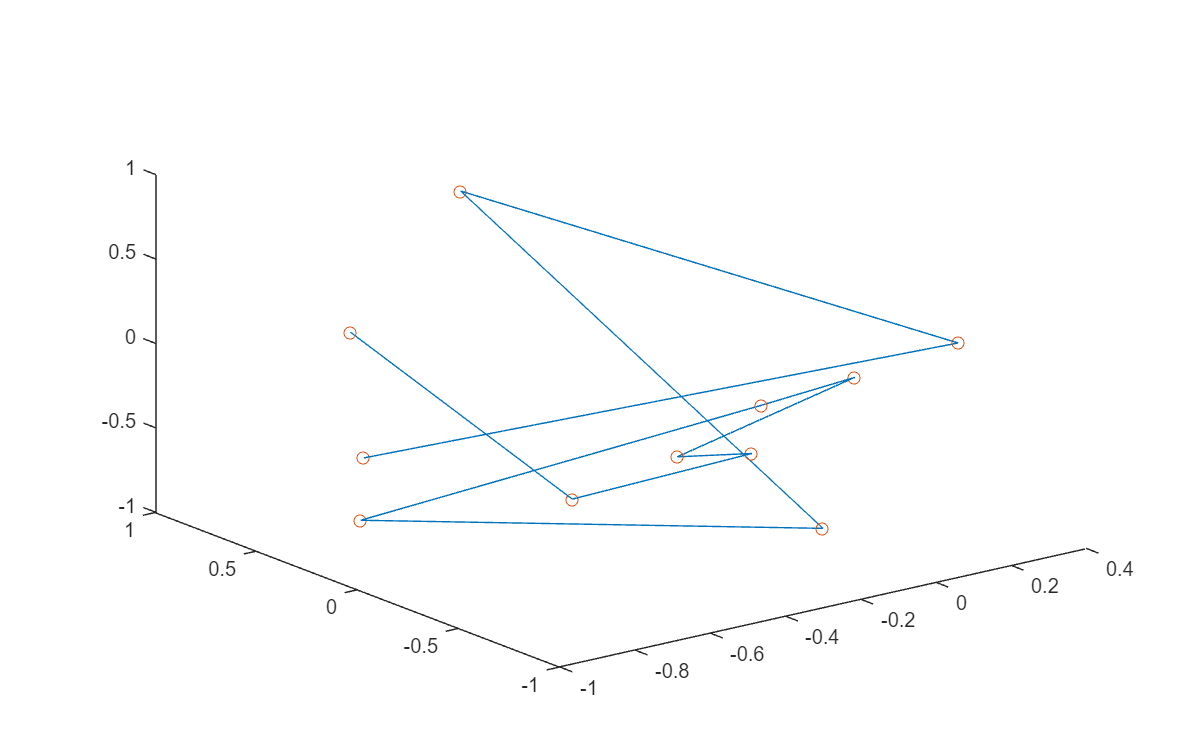


% Correction: fixed hidlayersrn() 
plot3(h(:,1),h(:,2),h(:,3))
hold on
scatter3(h(:,1),h(:,2),h(:,3))

## Attachments

function babynet = initorigbcm( nin,range,rs )
%initialize bcm cell
rng(rs);
babynet.wts=range*(rand(1,nin)-0.5) ;
babynet.rb = 0 ;
end

function finalcell = origbcm( initcell, pset, niter, dt, rs )
%iterates iterbcm
cell=initcell;
avgpat=sum(pset,2)/size(pset,2);
rng(rs) ;
for i=1:niter
    apat = pset(:,irand(size(pset,2),1)) ;
    r=cell.wts*apat ;
    cell.rb = cell.wts*avgpat ;
    cell.wts = cell.wts + dt*r*(r-cell.rb*cell.rb)*apat' ;
end
finalcell=cell;
end

% SRN

% Generate strings
function strings = makestringlist(tgram,nstrings)
jj=1; % initial state
strings.list=[];
strings.states=[];
nstates=size(tgram.prob,2);
for ii=1:nstrings
    strings.ind(ii)=jj ; %index into superstring
    seq=[]; %initialize one string
    st=1;
    stlist=[] ; %initial state list
    while (st<nstates)
        rr=rand();
        cumu=0; i=0;
        while (cumu<rr)
            i=i+1;
            cumu=cumu+tgram.prob(st,i);
        end
        letter=tgram.ind(st,i) ;
        seq=[seq letter];
        stlist=[stlist st];
        st=i;
    end
    seq=[seq nstates] ; % append end character to seq
    strings.list=[strings.list seq];
    jj=jj+size(seq,2);
    strings.states=[strings.states stlist];
end
end



% Initialize weights
function netstruct=initnet3srnx(n1,n2,n3,uamp,vamp,rs)
rng(rs);
netstruct.wih=uamp*(rand(n2,n1)-0.5) ;
netstruct.hh=uamp*(rand(n2,n2)-0.5) ;
netstruct.hbias=uamp*(rand(1,n2)-0.5) ;
netstruct.whout=vamp*(rand(n3,n2)-0.5) ;
netstruct.obias=vamp*(rand(1,n3)-0.5);
netstruct.context=zeros(1,n2);
end

% Main program
function finalnet=bp3srn(net0,strlist,niter,eta,nlev)
netk=net0;
for i=1:niter
    ts=selectstring(strlist) ; % choses a new string from the training set
    netk.context=zeros(1,size(netk.wih,1)); % rests the context for a new string
    for j=1:size(ts,2)-1 % this loop trains a single string
        netk=cyc3srn(netk,ts(j),ts(j+1),eta,nlev) ;
    end
end
finalnet=netk;
end


% chose training string
function sg = selectstring(sdata)
j=randi(size(sdata.ind,2)) ;
if (j<size(sdata.ind,2)) sg=sdata.list(sdata.ind(j):sdata.ind(j+1)-1);
else sg=sdata.list(sdata.ind(j):size(sdata.list,2)) ;
end
end


% Computes activities
function netact=forw1p3srn(netwk,p,nois)
netact.hid=hidlayersrn(p,netwk.context,netwk.wih,netwk.hh,netwk.hbias,nois);
netact.out=layersig01(netact.hid,netwk.whout,netwk.obias) ;
end


% Computes errors and adjusts weights
function newstruct=cyc3srn(nstruct,pin,pout,dt,noi)
newstruct=nstruct;
activity=forw1p3srn(nstruct,pin,noi) ;
tvec=zeros(size(nstruct.obias)) ;
tvec(pout)=1;
odelt=tvec-activity.out; %output deltas
hdelt=0.5*(nstruct.whout'*odelt').*(1+activity.hid').*(1-activity.hid');%hid deltas
%adjust weights and biases
newstruct.whout=newstruct.whout+dt*odelt'*activity.hid ;
newstruct.obias=newstruct.obias+dt*odelt ;
newstruct.wih(:,pin)=newstruct.wih(:,pin)+dt*hdelt; %just update weights from active input
newstruct.hbias=newstruct.hbias+dt*hdelt' ;
newstruct.hh=newstruct.hh+dt*hdelt*nstruct.context ;
newstruct.context=activity.hid ;
end



function [sout,hlist,slist] = stringprocv4X(netwk,strg,gramm)
hlist=[] ;
ctxinp=zeros(1,size(netwk.wih,1));
slist=[] ;
lets=gramm.labels(strg)

%STRINGS!!!
s1=[] ;
sout=[];

for j=1:size(strg,2)-1
    hhh=hidlayersrn(strg(j),ctxinp,netwk.wih,netwk.hh,netwk.hbias,0.0);
    ou=layersig01(hhh,netwk.whout,netwk.obias);
    hlist=[hlist;hhh] ;
    s1=[s1,lets(j)];
    scell=cellstr(s1) ;
    slist=[slist;scell] ;
    sout=[sout, sprintf('%c %c',gramm.labels(strg(j)), gramm.labels(strg(j+1)))] ;
    for kk=1:size(netwk.whout,1)
        sout=[sout sprintf('%6.3f',ou(kk))];
    end
    sout=[sout, sprintf('\n')];

    ctxinp=hhh;
end
end

function lout=hidlayersrn(pin,ctx,win,wctx,b,noise)
lll=b'+win(:,pin)+wctx*ctx';% FIXED %combine input from single input and ctx layer
lout=sigpn(lll)'+noise*(rand(size(lll))'-0.5);
end